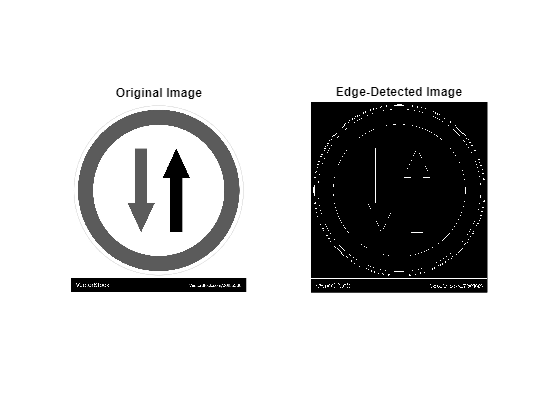

% Read the image
I = imread('2-way.jpg');

% Convert the image to grayscale if it's not already
if size(I, 3) == 3
    I = rgb2gray(I);
end

% Apply Gaussian smoothing
I_smoothed = imgaussfilt(I, 1);

% Apply edge detection using the Canny method
edge_image = edge(I_smoothed, 'Canny');

% Display the original and edge-detected images
figure;
subplot(1, 2, 1);
imshow(I);
title('Original Image');

subplot(1, 2, 2);
imshow(edge_image);
title('Edge-Detected Image');